clear, clc, close all

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1         arm1         jnt1     revolute             base(0)   arm2(2)  
   2         arm2         jnt2     revolute             arm1(1)   arm3(3)  
   3         arm3         jnt3        fixed             arm2(2)   
--------------------


ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


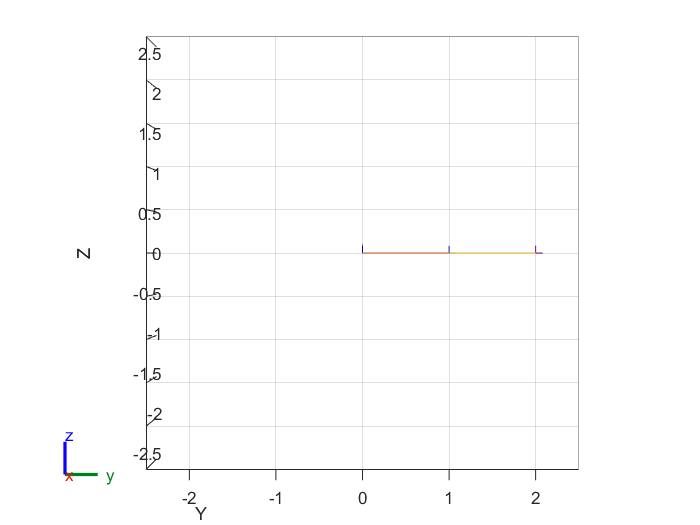

% Create robot
robot = create_robot_tree(1);

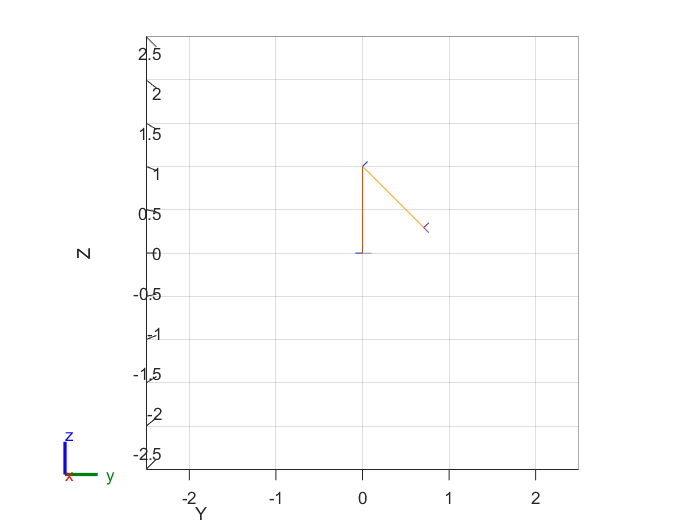

robot.Gravity = [0 0 -9.81];
config = homeConfiguration(robot);
pose = [pi/2; -3*pi/4];
show(robot,pose);
xlim([-.01,.01])
view(90,0)

nJoints = 2;
% gui = interactiveRigidBodyTree(robot,"MarkerScaleFactor",0.25);
m1 = 1; 
m2 = 1;
L1 = 1;
L2 = 1;
l1 = 0.5;
l2 = 0.5;
g = 9.81;

% Test simulation of nonlinear robot dynamics
u_test = @(t) 0*t;
tspan = [0,5];
x0 = [pose;0;0];
[t_test,x_test] = sim_robot(robot,u_test,x0,tspan);

% Animate response
q_test = x_test(:,1:nJoints);
count = size(q_test,1);
rate = 0.01;
show(robot,q_test(1,:)');
xlim([-.01,.01])
view(90,0)
while true
    for i = 1:count
        show(robot,q_test(i,:)','PreservePlot',false);
        xlim([-.01,.01])
        view(90,0)
        drawnow
        pause(rate);
    end
    pause(0.5);
end % Need to manually stop execution here

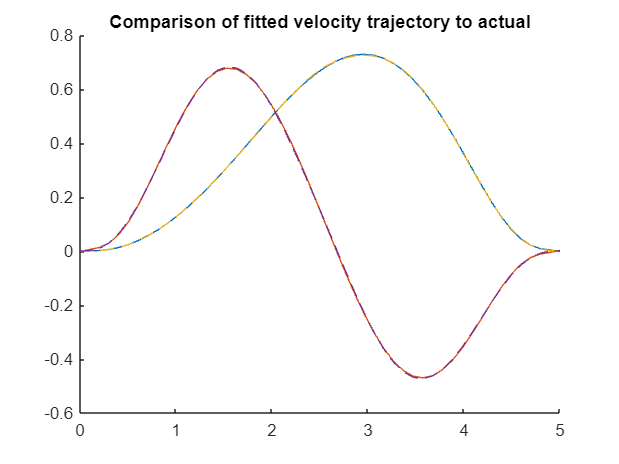

% Create trajectory
ik = inverseKinematics('RigidBodyTree',robot);
% ignore orientation for now
weights = [0 0 0 1 1 1];

% Create waypoints:
x0 = [0 1 0.5];
xw = [0 0 1.75];
xf = [0 -1 1];
x = [x0; xw; xf];

% Equally spaced time points for each waypoint, can change this
tf = 5;
n = size(x,1);
tpts = linspace(0,tf,n);

% Timing parameter
r = .1; % This affects how many discrete points there are in the 
% trajectory, and is the main driver of error in the inverse dynamics
% controller below

% Solve for cubic trajectory
% [qt, qtd, qtdd, tpp] = create_cubic_traj(robot,weights,x,tpts,r,pose);

% Solve for minimum jerk trajectory
[qt,qtd,qtdd,qtddd,tpp,tPoints,tSamples] = create_minjerk_traj(robot,weights,x,tpts,r,pose);

% Actually going to be interested in piecewise polynomial tpp, 
% which can be evaluated at an arbitrary time

% Also need velocity of the trajectory as a function of time
order = 10; % Is 10 good enough?
qdp1 = polyfit(tSamples,qtd(1,:),order); 
qdp2 = polyfit(tSamples,qtd(2,:),order);
% Compare true to fitted graphically
figure()
hold on
title("Comparison of fitted velocity trajectory to actual")
plot(tSamples,polyval(qdp1,tSamples))
plot(tSamples,polyval(qdp2,tSamples))
plot(tSamples,qtd,'--')


% Animate Trajectory
% animate_traj(robot,qt,r) % Need to manually stop execution

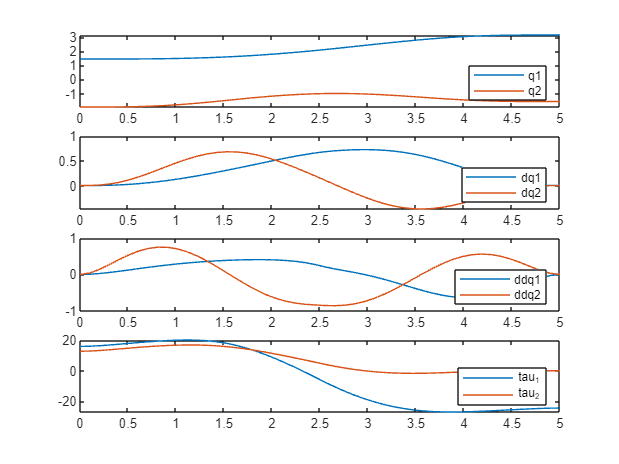

% Create an inverse dynamics controller for the trajectory
% Plot trajectory
n_traj = size(qt,2);
xt = linspace(0,tf,n_traj);
figure
subplot(4,1,1)
plot(xt,qt)
legend("q1","q2",'Location','southeast')
subplot(4,1,2)
plot(xt,qtd)
legend("dq1","dq2",'Location','southeast')
subplot(4,1,3)
plot(xt,qtdd)
legend("ddq1","ddq2",'Location','southeast')

% This gets torques required for the acceleration at each trajectory point
tau_t = zeros(size(qt));
for i=1:n_traj
    ti = i/n_traj*tf;
    tau_t(:,i) = inverse_dynamics_controller(ti,robot,qt,qtd,qtdd,xt);
end
subplot(4,1,4)
plot(xt,tau_t)
legend("tau_1","tau_2",'Location','southeast')

% Test for the robot
k_null = @(t) zeros(2,4); % No lqr gains at first
u_traj = @(t) inverse_dynamics_controller(t,robot,qt,qtd,qtdd,xt);
q_traj = @(t) [ppval(tpp,t)]; % Disregard velocity trajectory
q_traj_full = @(t) [ppval(tpp,t); polyval(qdp1,t); polyval(qdp2,t)];

x0 = [qt(:,1);0;0]; % No starting position error
opts = odeset('RelTol',1e-4,'AbsTol',1e-6); % These settings give good results. It's sensitive to number of time steps, obviously
% opts = [];
[t_sim,x_sim] = sim_robot_lqr(robot,k_null,q_traj,u_traj,x0,[0,tf],opts);
q_sim = x_sim(:,1:nJoints)';
% animate_traj(robot,q_sim,0.01)

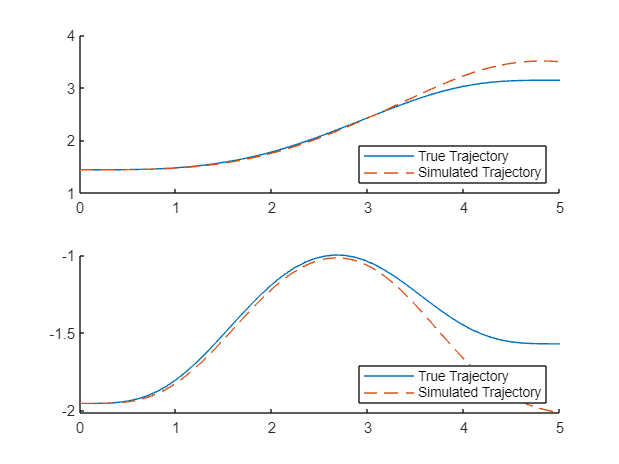

% Plot trajectory from controller vs. true desired trajecory
figure
title("Inverse Dynamics Controller")
subplot(2,1,1)
hold on
plot(tSamples,qt(1,:))
plot(t_sim,q_sim(1,:),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')
subplot(2,1,2)
hold on
plot(tSamples,qt(2,:))
plot(t_sim,q_sim(2,:),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')

% This blo,ck gets the A,B matrices as functitons of state
% q and input vars u
[q_ddot, q_dot, q, u, vars] = robot_arm_dynamics();
[A,B,dq,du] = linearize_around_state(q_ddot,q,u);

% Set parameters
params = [m1 m2 L1 L2 l1 l2 g]; % Is g positive or negative??
A2 = subs(A,vars,params);
B2 = subs(B,vars,params);

% Set trajectory/input variables
% can ignore velocity component because linearization doesn't depend on it
vars2 = [formula(q);formula(u)];
eval_vars = @(t) [q_traj(t);u_traj(t)];

% Create A,B matrices as functions of time
At = @(t) eval_mat(A2,vars2,eval_vars,t);
Bt = @(t) eval_mat(B2,vars2,eval_vars,t);

% Set lqr params
Q = @(t) diag([10000,10000,0,0]);                            
R = @(t) eye(nJoints);                         
S_tf = diag([100000,100000,0,0]); 
tspan = [0,tf];

[time,K] = tvLQR(At,Bt,Q,R,S_tf,tspan);
K_f = flip(K,3); % These are in reverse order
time_f = flip(time);

% Test another way of trajectory LQR, lines up pretty well
linSys = @(t) [At(t), Bt(t)];
num_t = 300;
tlqr = linspace(0,tf,num_t);
Ql = Q(0);
Rl = R(0);
Soln = trajectoryLqr(tlqr,linSys,Ql,Rl,S_tf,1e-6);
Kl = reshape([Soln.K],[2,4,num_t]);
timel = [Soln.t];

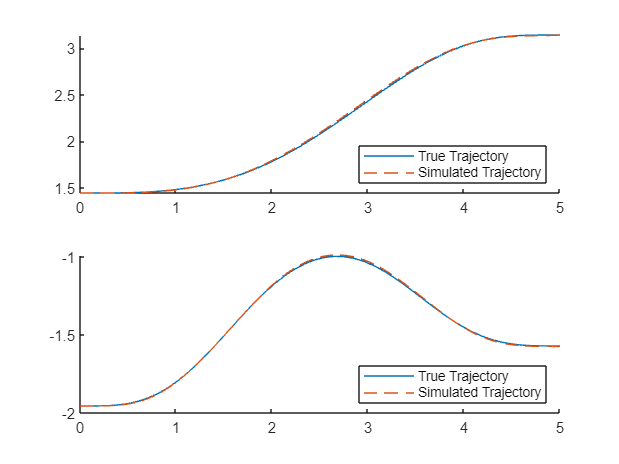

% Now create gains as a function in time
% Kt = @(t) piecewise_gains(K_f,time_f,t); % 2x4 gain matrix
Kt = @(t) piecewise_gains(Kl,timel,t);

% Set initial state
x0 = [qt(:,1);0;0];

opts = odeset('RelTol',1e-4,'AbsTol',1e-6);
% opts = [];
[t_sim,x_sim] = sim_robot_lqr(robot,Kt,q_traj_full,u_traj,x0,[0,tf],opts);
r = 0.01;
q_sim = x_sim(:,1:nJoints)';

% animate_traj(robot,q_sim,r)

% Plot trajectory from controller vs. true desired trajecory
figure()
subplot(2,1,1)
hold on
plot(tSamples,qt(1,:))
plot(t_sim,q_sim(1,:),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')
subplot(2,1,2)
hold on
plot(tSamples,qt(2,:))
plot(t_sim,q_sim(2,:),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')

% Now implement time varying kalman filter: https://www.mathworks.com/help/control/ug/kalman-filtering.html


% TODO Implement the extended kalman filter: https://www.mathworks.com/help/fusion/ug/extended-kalman-filters.html
